% Dynamical Model of two link Planar Manupulator 

% motor properties
amax=1.05; %[rad/s^2]
mm = [0.3, 0.3];
Im = [1, 1];
kr = [1/10,1/5];

% link dimension
lx=[1 1];
ly=[1 1];
lz=[1 1];

%material properties
density= 2660 ; % [kg/m3] AW 5083 alloy
rho=(density*1000)/100^3; %[g/cm3]

mass=[rho*lx(1)*ly(1)*lz(1) rho*lx(2)*ly(2)*lz(2)];


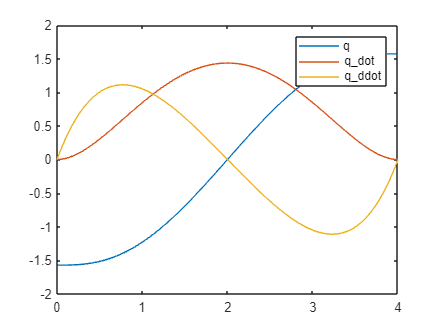

methods = dynlib;
t_end = 4;
[A, vandermont] = methods.criticaltrajectory(t_end, amax);
%A = methods.polynomial([-pi/2; 0; pi/2], [0; 0], [0; amax; 0], [0, t_end/2, t_end], [0, t_end], [0, t_end/4, t_end]);
t = [0:0.01:t_end];
y = [];
for i=1:length(t)
    y=[y;A'*methods.vand(t(i), 7)', A'*methods.devand(t(i),7)', A'*methods.dedevand(t(i),7)'];
end
plot(t,y);
legend("q", "q\_dot", "q\_ddot");

[B, C, g] = methods.dyn(lx,ly,lz,rho, mm, Im, kr)

$$B = \left(\begin{array}{cc} \frac{3\,\cos\left(\bar{q_{1}}\right)\,\cos\left(q_{1}\right)}{500}+\frac{3\,\sin\left(\bar{q_{1}}\right)\,\sin\left(q_{1}\right)}{500}+\frac{177173}{79800} & \frac{17837}{15960}-\frac{\sin\left(q_{1}\right)}{2}-\frac{\cos\left(q_{1}\right)}{2}\\ \frac{17837}{15960}-\frac{\sin\left(\bar{q_{1}}\right)}{2}-\frac{\cos\left(\bar{q_{1}}\right)}{2} & \left(\cos\left(q_{1}\right)-\frac{50}{133}\right)\,\left(\frac{133\,\cos\left(\bar{q_{1}}\right)}{100}-\frac{1}{2}\right)+\left(\frac{133\,\sin\left(\bar{q_{1}}\right)}{100}-\frac{1}{2}\right)\,\left(\sin\left(q_{1}\right)-\frac{50}{133}\right)+\frac{89}{120} \end{array}\right)$$

$$C = \begin{array}{l} \left(\begin{array}{cc} 0 & {\mathrm{dq}}_{2}\,\sigma_{1}-{\mathrm{dq}}_{1}\,\left(\frac{\cos\left(\bar{q_{1}}\right)}{4}-\frac{\sin\left(\bar{q_{1}}\right)}{4}+\frac{\cos\left(q_{1}\right)}{4}-\frac{\sin\left(q_{1}\right)}{4}\right)\\ -{\mathrm{dq}}_{2}\,\sigma_{1} & {\mathrm{dq}}_{1}\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\cos\left(q_{1}\right)\,\left(\frac{133\,\sin\left(\bar{q_{1}}\right)}{100}-\frac{1}{2}\right)}{2}-\frac{\sin\left(q_{1}\right)\,\left(\frac{133\,\cos\left(\bar{q_{1}}\right)}{100}-\frac{1}{2}\right)}{2}+\frac{133\,\cos\left(\bar{q_{1}}\right)\,\left(\sin\left(q_{1}\right)-\frac{50}{133}\right)}{200}-\frac{133\,\sin\left(\bar{q_{1}}\right)\,\left(\cos\left(q_{1}\right)-\frac{50}{133}\right)}{200} \end{array}$$

$$g = 0$$

syms("q1","q2","dq1","dq2");
Bq=simplify(subs(B,[q1,q2,dq1,dq2],[pi/2,pi/2,0.1,0.1]))

$$Bq = \left(\begin{array}{cc} \frac{888259}{399000} & \frac{9857}{15960}\\ \frac{9857}{15960} & \frac{115519}{79800} \end{array}\right)$$

Cq=simplify(subs(C,[q1,q2,dq1,dq2],[pi/2,pi/2,0.1,0.1]))

$$Cq = \left(\begin{array}{cc} 0 & \frac{1}{10}\\ -\frac{1}{20} & \frac{1}{20} \end{array}\right)$$